# Denoising Using Low-Rank Approximation

## Introduction

The idea is  to identify the best way to approximate a given matrix $A$ with another one with a lower rank. Such a matrix is called a *low-rank approximation. *Usually, these methods imply imposing the target rank $k$, but in this tutorial we will focus on a relaxation using the nuclear norm.

**Low-Rank Structure in Data**

Many real-world datasets, especially those related to images, videos, and sensor readings, exhibit an underlying low-rank structure. This means that the essential information contained in the data can be represented by a matrix with significantly fewer non-zero singular values. For example, in images, pixels are often highly correlated due to the continuous nature of visual scenes, resulting in a low-rank representation. This redundancy can be exploited to distinguish between the meaningful signal and the random noise.

#### **Applications**

- **Compression - ** A low-rank approximation offers a compressed (albeit lossy) version of the matrix. While the original matrix A of size n x m is represented by nm numbers, describing it as a rank k matrix allows it to be eexpressed as $XY^T$ where $X$ is of size $n \times k$ and $Y$ of size $m \times k$, which  only requires  $k(n+m)$ numbers. If $k$ is small compared to $n$ and $m$, substituting their product with their sum yields significant savings.

- **Robust PCA - **Another example of matrix optimization problem involving a nuclear norm regularization is robust PCA. More generally, matrix optimization problems involving sparsity promoting criteria find broad applications in Data Science since they are at the core of techniques such as GLASSO or matrix completion.

- **Denoising -** If $A$ is a noisy version of some "ground truth" signal that is approximately low-rank, then approximating $A$ with a low-rank matrix can effectively reduce noise while preserving the signal. This process results in a matrix that is more informative than the original noisy data.

- **Updating Big ML Models -  ** One modern application of low-rank matrix approximations is for fine-tuning large models. In the context of large language models (LLMs) with billions (or more) parameters, one often uses an off-the-shelf model trained on a vast, generic corpus (e.g., text from the web). Fine-tuning involves a second round of training on a domain-specific dataset, which is typically much smaller. Examples of fine-tuning tasks include datasets of customer service exchanges, Ed forum questions and answers, medical reports, etc. The challenge with fine-tuning is the computational expense of updating such large models. The 2021 paper "LORA: Low-Rank Adaptation of Large Language Models"  argues that fine-tuning updates are generally close to low-rank, and  one can explicitly learn these updates in their factorized form, effectively reducing the number of parameters to be trained.

Let's get started!

clear all
close all
clc

## 1. Load image and degrade data

We consider a denoising problem. We want to approximate the original image $x$ which was corrupted by additive noise.

$\tilde{x} = x + n$ , where $n\in \mathcal{N}(0, \alpha I)$.

You should create your own version of noisy image. 

Load the images provided in the folder and add a perturbation. You can control the perturbation level. Reseize the image to make it square.


N = 256;
Xtrue = imread('circ.png');
Xtrue = im2double(rgb2gray(Xtrue));
Xtrue = imresize(Xtrue, [N,N]);


% create the noisy version of the image
% sb = 0.2;
% Xtilde = ....;


Now plot the two images $x$ and $\tilde{x}$.

figure(1)
figure(2)

### 2. Dual Forward Backward

For this denosing problem we focus on nuclear norm penalization, considering the following optimization problem.

$x_\gamma = \text{argmin}_x \quad \frac{1}{2}\|\tilde{x} - x\|_{\rm{F}}^2 + \gamma\| x\|_*$,

where $\| \cdot \|_F$ is the Frobenius norm and $\| \cdot\|_*$ is the nuclear norm, i.e. the sum of the singular values of $x$. The nuclear norm regularization encourages the solution to have a low rank, making it effective in denoising.

To solve our problem, we will use Dual Forward-Backward algorithm, which is one of the most powerful proximal methods. The algorithm to be implemented is as follows.

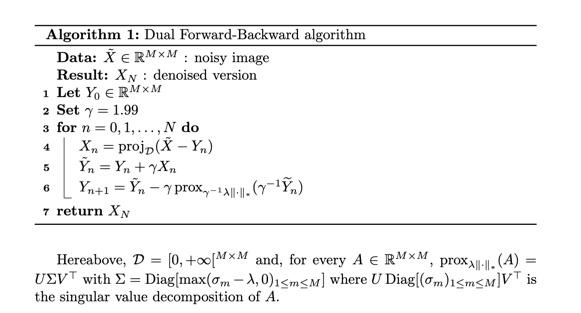

Implement the algorithm and play with different values of the hyperparameters to obtain the best results. Check the cost at each iteration and stop the algorithm if it reaches a certain precision.

edit DFB.m

### 3. Accelerated Dual-Forward Backward

There is also possible to implement an accelerated version of the algorithm. 

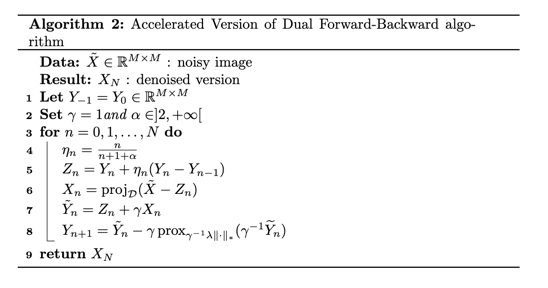

Write a Matlab function that implements the FISTA algorithm. Play with different values of the hyperparameters to obtain the best results. Check the cost at each iteration and stop the algorithm if it reaches a certain precision.

edit DFBa.m

### 4. Comparison

Compare the two methods from the convergence speed view-point. Plot the convergence curves of both algorithms on the same graph. 

nitm = 250;
lambda = 5;
prec = 1e-7;

[X,Y,cost,niter] = DFB(Xtilde,lambda,nitm,prec);

Unrecognized function or variable 'Xtilde'.

[X_F,Y_F,cost_F,niter_F] = DFBa(Xtilde,lambda,nitm,prec);

Compute the cost $\| x_N - x\|_{\rm{F}}$

% loss_dfb = .... 
% loss_dfba = ....

Plot the results.

gcf = figure(3);
gcf.Position(3) = 1300;
hold on;
subplot(1,2,1)
imagesc(X)
colormap(gray(256))
title(sprintf("DFB, Nr. iter: %d , cost: %d",niter,cost(end)))

subplot(1,2,2)
imagesc(X_F)
colormap(gray(256))
title(sprintf("FISTA-DFB; Nr. iter: %d ; cost: %d",niter_F,cost_F(end)))

Plot the convergence curve.

figure(4)

### 5. Discussion

- What is the effect of the regularizer $\lambda$?

- Will this method work on all images? What are the best suited domains?

- What are the best values for the hyperparameters? Why?